# ***B. subtilis***** FBA**

**By UCL iGEM 2020 **

**(Anna Su)**

**For our partner Exeter iGEM 2020 :)**

## Initilization of COBRA

initCobraToolbox(false)



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.24.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

## Reading SBML & Outputing Spreadsheet

% load the original GEM of B. subtilis
original_model = readCbModel('iYO844.xml');
% print out a spreadsheet
writeCbModel(original_model, 'xls', 'B. subtilis.xls');

## Making a Copy of the Original Model

% copy the original model. This ensures that no changes are made in the original model
model = original_model

model = struct with fields:
                                    S: [990×1250 double]
                                 mets: {990×1 cell}
                                    b: [990×1 double]
                               csense: [990×1 char]
                                 rxns: {1250×1 cell}
                                   lb: [1250×1 double]
                                   ub: [1250×1 double]
                                    c: [1250×1 double]
                            osenseStr: 'max'
                                genes: {844×1 cell}
                                rules: {1250×1 cell}
                            geneNames: {844×1 cell}
                            compNames: {2×1 cell}
                                comps: {2×1 cell}
                             proteins: {844×1 cell}
                           metCharges: [990×1 double]
                          metFormulas: {990×1 cell}
                             metNames: {990×1 cell}
                           

## **Growth on Glucose**

**Proof that the model we chose is well curated:**

growth = 0.5186 @ glucose = -6.2 & oxygen unbounded

In line with literature (Figure 2 in "Genome-scale Reconstruction of Metabolic Network in Bacillus subtilis Based on High-throughput Phenotyping and Gene Essentiality Data")

glucose = model;
glucose = changeRxnBounds(glucose,'EX_glc__D_e',-6.2,'l');
glucose = changeObjective(glucose,'BIOMASS_BS_10');
growth_glucose = optimizeCbModel(glucose,'max')

growth_glucose = struct with fields:
    origStatText: []
               f: 0.5186
               v: [1250×1 double]
               y: [990×1 double]
               w: [1250×1 double]
               s: [990×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.1949
           basis: []
          vars_v: []
               x: [1250×1 double]


max growth = 0.6242 @ glucose = -7.4 & oxygen unbounded

glucose = model;
glucose = changeRxnBounds(glucose,'EX_glc__D_e',-7.4,'l');
glucose = changeObjective(glucose,'BIOMASS_BS_10');
growth_glucose = optimizeCbModel(glucose,'max')

growth_glucose = struct with fields:
    origStatText: []
               f: 0.6242
               v: [1250×1 double]
               y: [990×1 double]
               w: [1250×1 double]
               s: [990×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.1073
           basis: []
          vars_v: []
               x: [1250×1 double]


## Adding Reactions

% set up a baseline model
base = model;

% 2 reactions for getting h2co3
base = addReaction(base, 'CA', 'co2[e] + h2o[e] <=> h2co3[e]');
base = addReaction(base, 'UREASE', 'urea[e] + 2h2o[e]<=> h2co3[e] + 2nh3[e]');

% h2co3 <=> hco3 <=> co3
base = addReaction(base, 'BICARB', 'h2co3[e] <=> hco3[e] + h[e]');
base = addReaction(base, 'CARB', 'hco3[e] + oh[e] <=> co3[e] + h2o[e]');

% nh3 <=> nh4
base = addReaction(base, 'AMM', 'nh3[e] + h2o[e] <=> nh4[e] + oh[e]');

% adding a reaction for draining co3
base = addReaction(base, 'EX_CO3_e', 'co3[e] <=> ');

% adding a reaction for draining oh
base = addReaction(base, 'EX_OH_e', 'oh[e] <=> ');

## Growth on Lactose

C₁₂H₂₂O₁₁

biomass growth = 0.5768/ h

lactose = -4 mmol/gDCW/h & oxygen unbounded

lactose = base;
lactose = changeRxnBounds(lactose,'EX_glc__D_e',0,'l');
lactose = changeRxnBounds(lactose,'EX_lcts_e',-4,'l');
growth_lactose = optimizeCbModel(lactose,'max')

growth_lactose = struct with fields:
    origStatText: []
               f: 0.5768
               v: [1257×1 double]
               y: [997×1 double]
               w: [1257×1 double]
               s: [997×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0666
           basis: []
          vars_v: []
               x: [1257×1 double]


## Carbonate Production

carb = lactose;

% block the urea transport reaction to keep flux extracellular
carb = changeRxnBounds(carb, 'UREAt', 0, 'l');

% constrain biomass
carb = changeRxnBounds(carb, 'BIOMASS_BS_10', 0.2, 'l');

% provide CO2 and urea
carb = changeRxnBounds(carb, 'EX_co2_e', -20, 'l');
carb = changeRxnBounds(carb, 'EX_urea_e', -20, 'l');

% maximize carbonate production
carb = changeObjective(carb, 'EX_CO3_e');
prod_co3_max = optimizeCbModel(carb,'max')

prod_co3_max = struct with fields:
    origStatText: []
               f: 80.8466
               v: [1257×1 double]
               y: [997×1 double]
               w: [1257×1 double]
               s: [997×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0592
           basis: []
          vars_v: []
               x: [1257×1 double]


## 2D: Growth vs Lactose Uptake

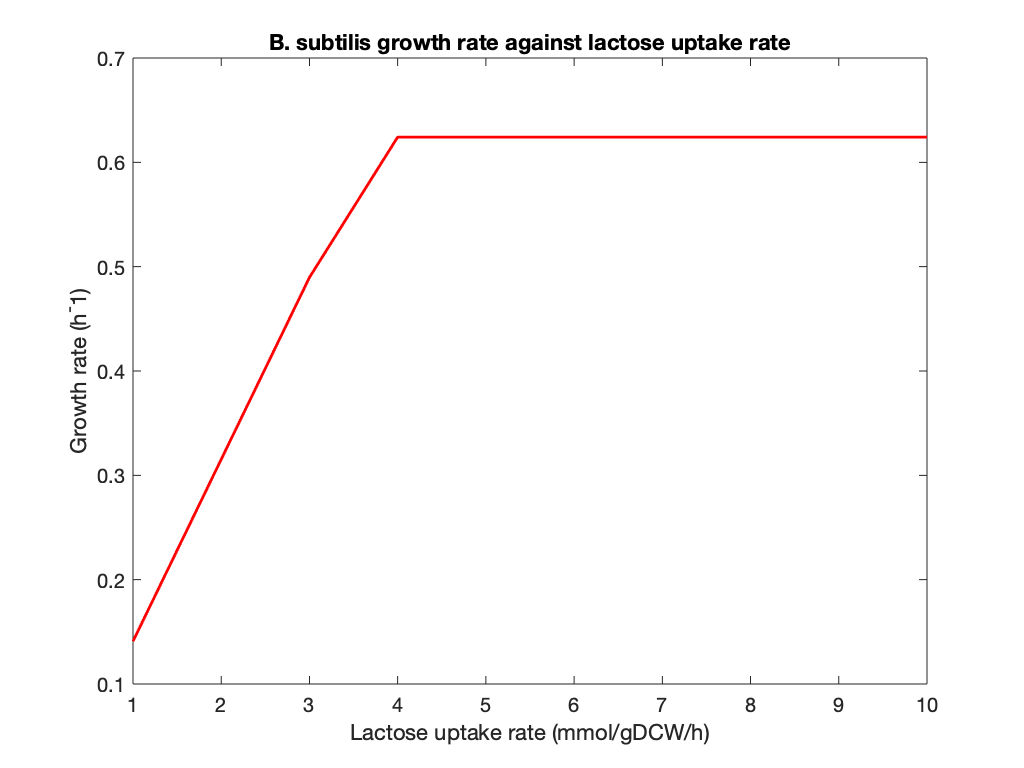

grow_plot = base;
uptake = -[1:10];
growth = zeros(10,1);
grow_plot = changeRxnBounds(grow_plot, 'EX_glc__D_e',0, 'l');  

for i = 1:10
    grow_plot = changeRxnBounds(grow_plot, 'EX_lcts_e', uptake(i), 'l'); 
    %optimization for biomass and get max flux
    sub = optimizeCbModel (grow_plot); 
    growth(i) = sub.f;
end

figure
grid on
plot(-uptake, growth, 'r','LineWidth',1.4)

xlabel('Lactose uptake rate (mmol/gDCW/h)');
ylabel('Growth rate (h^-1)');
title('B. subtilis growth rate against lactose uptake rate')

## 3D plot: Carbonate Production vs Urea Uptake vs CO2 Uptake

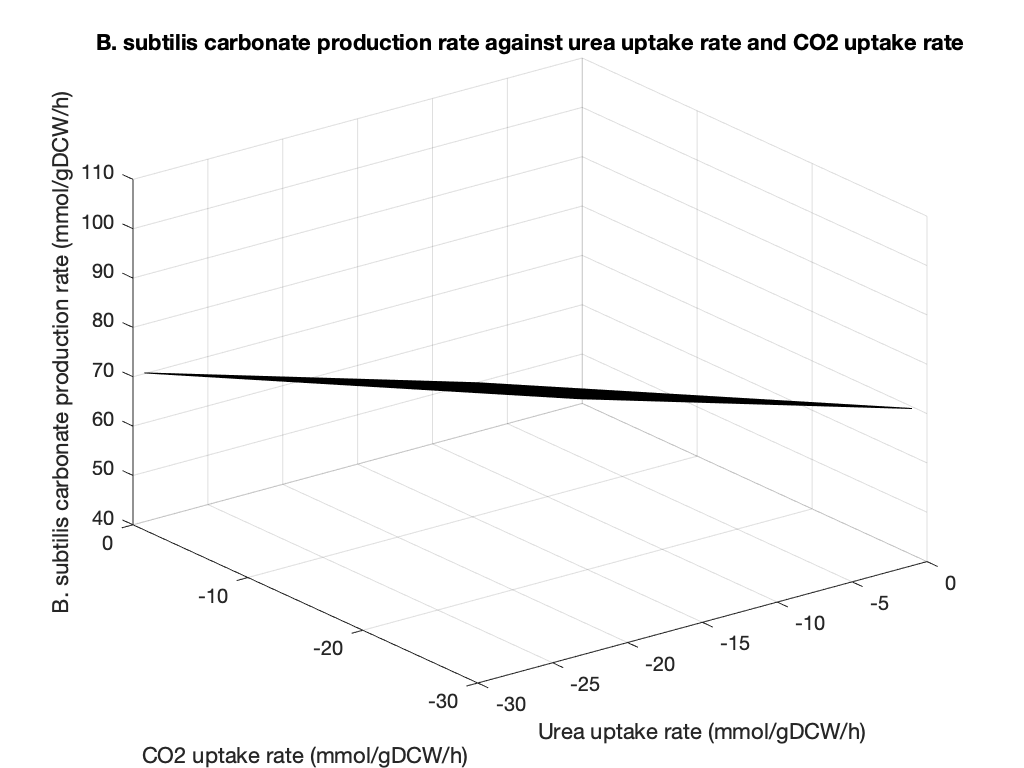

model_3Dplot = lactose;
urea_uptake = -[1:30];
co2_uptake = -[1:30];
lcts = zeros(30,30); 

model_3Dplot = changeRxnBounds(model_3Dplot, 'BIOMASS_BS_10', 0.2, 'l');
model_3Dplot = changeRxnBounds(model_3Dplot, 'EX_glc__D_e',0, 'l'); 
model_3Dplot = changeRxnBounds(model_3Dplot, 'UREAt', 0, 'l');
model_3Dplot = changeObjective(model_3Dplot, 'EX_CO3_e');

for i = 1:30
    for j = 1:30
        model_3Dplot = changeRxnBounds(model_3Dplot, 'EX_urea_e', urea_uptake(i), 'l'); 
        model_3Dplot = changeRxnBounds(model_3Dplot, 'EX_co2_e', co2_uptake(j), 'l');      
        lcts_FBAsolution = optimizeCbModel (model_3Dplot, 'max'); 
        lcts(i,j) = lcts_FBAsolution.f;  
    end
end

figure

surfl(urea_uptake, co2_uptake, lcts');
xlabel('Urea uptake rate (mmol/gDCW/h)');
ylabel('CO2 uptake rate (mmol/gDCW/h)');
zlabel('B. subtilis carbonate production rate (mmol/gDCW/h)')
title('B. subtilis carbonate production rate against urea uptake rate and CO2 uptake rate')

## Sinlge Gene Deletion

This program will tell you which single gene to knock out to produce the max carbonate production rate.

model_SGD = lactose;
model_SGD = changeRxnBounds(model_SGD, 'BIOMASS_BS_10', 0.2, 'l');
model_SGD = changeRxnBounds(model_SGD, 'BIOMASS_BS_10', 0.3, 'u');
model_SGD = changeRxnBounds(model_SGD,'EX_glc__D_e',0,'l');
model_SGD = changeRxnBounds(model_SGD, 'EX_co2_e', -20, 'l');
model_SGD = changeRxnBounds(model_SGD, 'EX_urea_e', -20, 'l');
model_SGD = changeObjective(model_SGD, 'EX_CO3_e');
[prodRatio, prodRateKO, prodRateWT, hasEffect, delRxns, fluxSolution] = singleGeneDeletion(model_SGD);

Single gene deletion analysis in progress ...
100%    [........................................]



% get the max carbonate production rate
carb_max = max(prodRateKO)

carb_max = 81.2651

% get the Ensembl ID of the gene to knock out
gene_to_knockout = model.genes(780)

gene_to_knockout = 1×1 cell array
    {'BSU21920'}


More info about this gene: [Gene BSU21920](https://bacteria.ensembl.org/Bacillus_subtilis_subsp_subtilis_str_168/Gene/Summary?g=BSU21920;r=Chromosome:2306514-2307662;t=CAB14110) 

## Flux Variability Analysis for Debugging

[FVA(:,1) FVA(:,2)] = fluxVariability(lactose, [], [], lactose.rxns);